Electricity Prices are modeled by $log(P_t) = f(t) + X_t$, where $P_t$ is the spot price of electricity, $f(t)$ is the deterministic seasonal part of the model, $X_t$ is the stochastic part.

$f(t) = s_1sin(2\pi t) + s_2cos(2\pi t) + s_3 sin(4\pi t) + s_4 cos(4\pi t) + s_5$ where $s_1, s_2,\dots , s_5 $ are constant parameters

$X_t$ is modeled as an Ornstein-Uhlenbeck process  $dX_t = (\alpha - kX_t)dt + \sigma dW_t + J(\mu_j, \sigma_j)d\Pi(\lambda)$where $\alpha,k$are mean reversion parameters, $\sigma $is volatility $W_t$is a standard Brownian Motion. $J(\mu_j, \sigma_j)$ is the jump size with a normally distributed mean $\mu_j$ and a standard deviation $\sigma_j$. Poisson process $\Pi(\lambda)$ has a jump intensity of $\lambda$

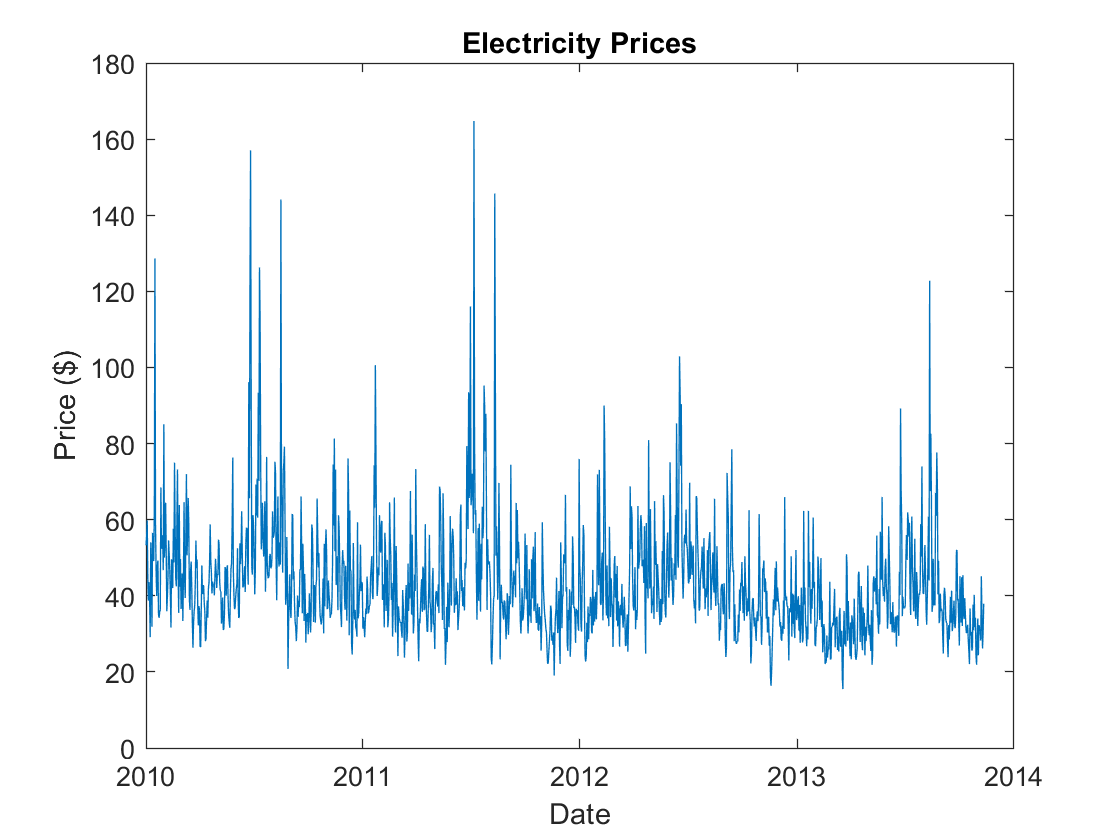

load('electricity_prices.mat');
figure
plot(PriceDates, Prices);
datetick();
title('Electricity Prices');
xlabel('Date');
ylabel('Price ($)');

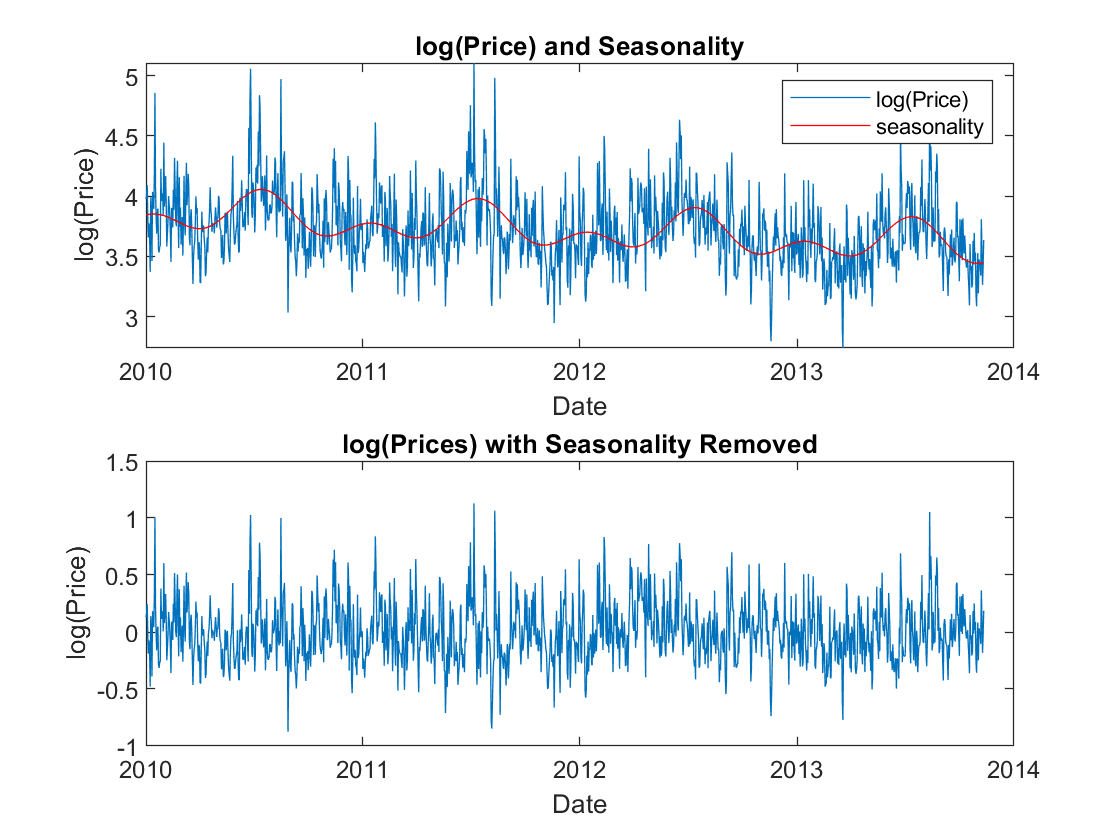

csvwrite('ElecDates.csv', PriceDates)
logPrices = log(Prices);
PriceTimes = yearfrac(PriceDates(1), PriceDates);

seasonMatrix = @(t) [sin(2.*pi.*t) cos(2.*pi.*t) sin(4.*t.*pi) cos(4.*pi.*t) t ones(size(t, 1), 1)];
C = seasonMatrix(PriceTimes);   
seasonParam = C\logPrices;

figure
subplot(2, 1, 1);
plot(PriceDates, logPrices);
datetick();
title('log(Price) and Seasonality');
xlabel('Date')
ylabel('log(Price)');
hold on;
plot(PriceDates, C*seasonParam,'r');
hold off
legend('log(Price)', 'seasonality');
X = logPrices - C*seasonParam;
subplot(2,1,2);
plot(PriceDates, X);
datetick();
title('log(Prices) with Seasonality Removed');
xlabel('Date');
ylabel('log(Price)');

The discretized equation for $X_t$ gives

$X_t = \alpha \Delta t + \phi X_{t-1} + \sigma \zeta$ with probability $(1 - \lambda \Delta t)$and

$X_t = \alpha \Delta t + \phi X_{t-1} + \sigma \zeta + \mu_j + \sigma_j\zeta_j$ with probability$\lambda \Delta t$ where $\zeta \ and \ \zeta_j$ are independant standard normal random variables and $\phi = 1 - k\Delta t$

$f(X_t |X_{t-1}) = (\lambda \Delta t)N_1(X_t|X_{t-1}) + ( 1 - \lambda \Delta t)N_2(X_t|X_{t-1})$ Where $N_1(X_t|X_{t-1}) = (2 \pi \sigma^2)^{-\frac {1}{2}}\; e^{{\frac {-(X_t - \alpha \Delta t - \phi X_{t-1} - \mu_j )^2}{2(\sigma^2 + \sigma^2_j)}}}}$ and $N_2(X_t|X_{t-1}) = (2 \pi \sigma^2) ^{-\frac{1}{2}} \; e^{\frac {-(X_t - \alpha \Delta t - \phi X_{t-1})^2}{2\sigma^2}$

paratmeters $\theta =  \{\alpha,\phi,\mu_j,\sigma^2,\sigma^2_j,\lambda \}$ is calibrated by minimizing the negative log likelihood function $min_{\theta} - \sum_{t=1}^{T} log(f(X_t|X_{t-1})
\\
subject \ to \ \phi < 1, \sigma^2 >0, \sigma^2_j > 0, 0 \leq \lambda \Delta t \leq 1$

Pt = X(2:end);
Pt_1 = X(1:end-1);

dt = 1/365;
mrjpdf = @(Pt, a, phi, mu_J, sigmaSq, sigmaSq_J, lambda) ...
    lambda.*exp((-(Pt-a-phi.*Pt_1-mu_J).^2)./(2.*(sigmaSq+sigmaSq_J))).* (1/sqrt(2.*pi.*(sigmaSq+sigmaSq_J))) + ...
    (1-lambda).*exp((-(Pt-a-phi .* Pt_1).^2)/(2.*sigmaSq)).* (1/sqrt(2.*pi.*sigmaSq));
lb = [-Inf, -Inf, -Inf, 0, 0, 0];
ub = [Inf, 1, Inf, Inf, Inf, 1];

x0 = [0, 0, 0, var(X), var(X), 0.5];
params = mle(Pt, 'pdf', mrjpdf, 'start', x0, 'lowerbound', lb, 'upperbound',ub,'optimfun','fmincon');

alpha = params(1)/dt

alpha =       -20.106


kappa = (1-params(2))/dt

kappa =        188.25


mu_J = params(3)

mu_J =       0.20435


sigma = sqrt(params(4)/dt)

sigma =         3.093


sigma_J = sqrt(params(5))

sigma_J =       0.26594


lambda = params(6)/dt

lambda =        98.336


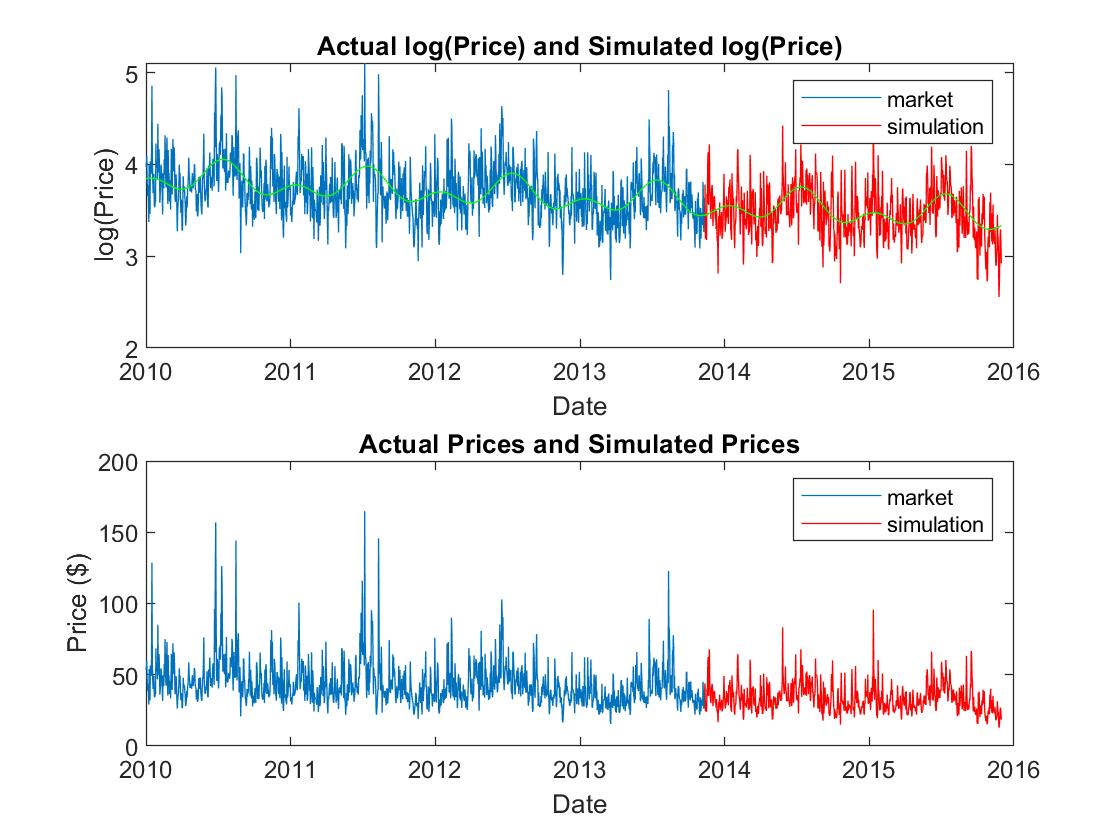



rng default

nPeriods = 365*2+20;
nTrials = 10000;
n1 = randn(nPeriods,nTrials);
n2 = randn(nPeriods,nTrials);
j = binornd(1, lambda*dt, nPeriods, nTrials);
SimPrices = zeros(nPeriods,nTrials);
SimPrices(1,:) = X(end);
for i=2:nPeriods
    SimPrices(i,:) = alpha*dt + (1-kappa*dt)*SimPrices(i-1,:) + sigma*sqrt(dt)*n1(i,:) + j(i,:).*(mu_J + sigma_J*n2(i,:));
end

SimPriceDates = daysadd(PriceDates(end), 0:nPeriods-1);
SimPriceTimes = yearfrac(PriceDates(1), SimPriceDates);
CSim = seasonMatrix(SimPriceTimes);
logSimPrices = SimPrices + repmat(CSim*seasonParam,1,nTrials);

figure
subplot(2,1,1);
plot(PriceDates, logPrices);
hold on
plot(SimPriceDates(2:end), logSimPrices(2:end,1) ,'red');
seasonLine = seasonMatrix([PriceTimes; SimPriceTimes(2:end)])*seasonParam;
plot([PriceDates; SimPriceDates(2:end)], seasonLine, 'green');
hold off;
datetick();
title('Actual log(Price) and Simulated log(Price)');
xlabel('Date');
ylabel('log(Price)');
legend('market', 'simulation');

PricesSim = exp(logSimPrices);
subplot(2,1,2);
plot(PriceDates, Prices);
hold on;
plot(SimPriceDates, PricesSim(:,1), 'red');
hold off;
datetick();
title('Actual Prices and Simulated Prices');
xlabel('Date');
ylabel('Price ($)');
legend('market', 'simulation');

FutPricesDaily = zeros(size(SimPriceDates));
for i=1:nPeriods
    idx = find(year(SimPriceDates(i)) == year(FutExpiry) & month(SimPriceDates(i)) == month(FutExpiry));
    FutPricesDaily(i) = FutPrices(idx);
end

SimPricesExp = mean(PricesSim, 2) 

SimPricesExp =        37.897
       35.523
       34.186
       33.477
       33.218
       33.093
       33.003
       32.937
       33.091
       33.161


We use $\ln \frac {F_t}{E_t} = -\sigma e^{-kt} \int\limits_{0}^{t} e^{ks}m_s\; ds$ to calibrate the market price of risk against market future values.

$F_t$ is the observed futures value at time $t$ 

$E_t$ is the expected value under the real-world measure at time $t$

$m_t$ is the market price of risk and can be solved for if the eq above is discretized

t0 = yearfrac(PriceDates(1), FutValuationDate);
tz = SimPriceTimes-t0;
b = -log(FutPricesDaily(2:end) ./ SimPricesExp(2:end)) ./ (sigma .* exp(-kappa .* tz(2:end)));
A = (1/kappa) .* (exp(kappa.*tz(2:end)) - exp(kappa.*tz(1:end-1)));
A = tril(repmat(A', size(A,1), 1));

P = diag(1./diag(A));
b = P*b;
A = P*A;

riskPremium = A\b

riskPremium =       -19.053
      -13.473
      -13.177
      -12.461
      -12.331
      -12.403
      -12.459
      -11.574
      -11.672
      -11.966


nTrials = 10000;
n1 = randn(nPeriods, nTrials);
n2 = randn(nPeriods, nTrials);
j = binornd(1, lambda*dt, nPeriods, nTrials);

SimPrices = zeros(nPeriods,nTrials);
SimPrices(1,:) = X(end);
for i=2:nPeriods
    SimPrices(i,:) = alpha*dt + (1 - kappa*dt)*SimPrices(i-1,:) + sigma*sqrt(dt)*n1(i,:) - sigma*dt*riskPremium(i-1) + j(i,:) .* (mu_J + sigma_J*n2(i,:));
end
CSim = seasonMatrix(SimPriceTimes);
logSimPrices = SimPrices + repmat(CSim*seasonParam,1,nTrials);
PricesSim = exp(logSimPrices)

PricesSim =        37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897       37.897
        36.17       33.441       34.647       46.946       33.832       40.339       40.373       34.854       34.893       32.224       58.753        39.36       29.151       39.431       38.136       35.918       46.959       32.516       38.283       27.061       38.327       34.433        46.22       63.607       54.516       23.20

risk-neutral simulation can be conducted after $m_t$ is computed from above. Then risk-neutral simulation can be conducted using the following dynamics.


$$X_t = a\Delta t + \phi X_{t-1} -\sigma m_{t-1}\Delta t + \sigma \zeta  \ with \ probability \ (1-\lambda \Delta t)
\\
X_t = a\Delta t + \phi X_{t-1} - \sigma m_{t-1} \Delta t + \sigma \zeta + \mu_j + \sigma_j \zeta_j \ with \ probability \ \lambda \Delta t$$


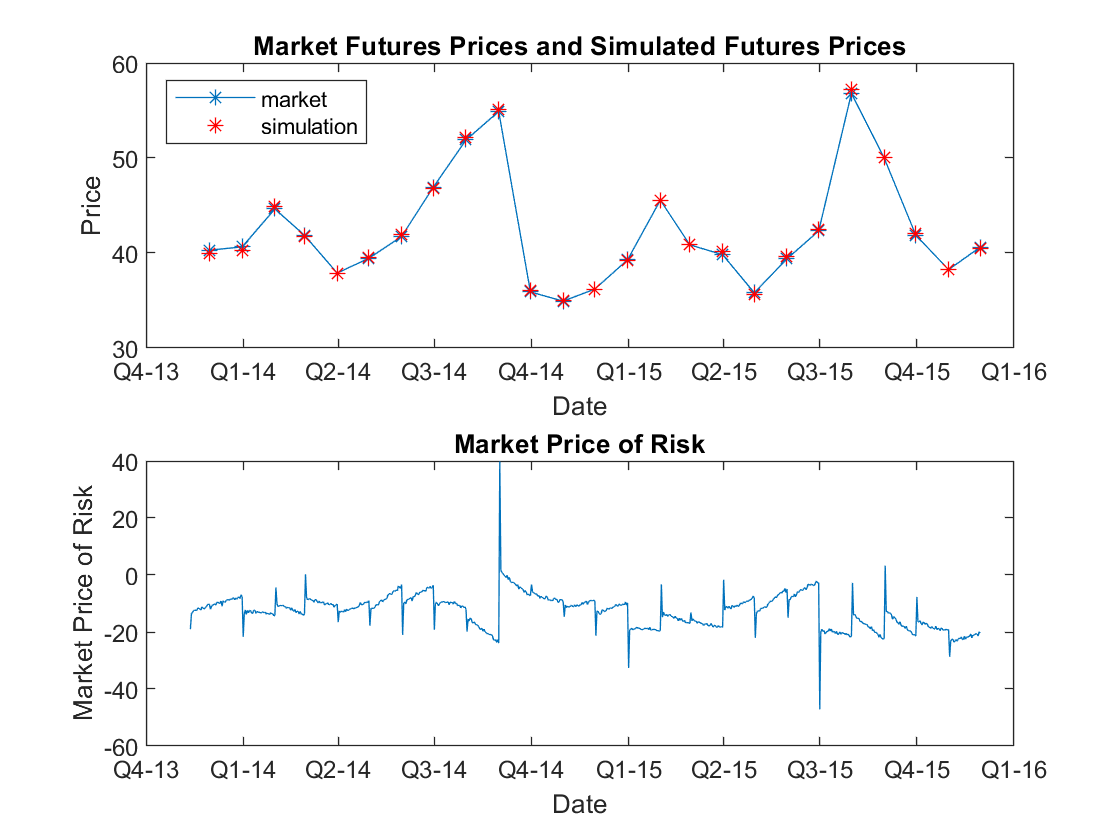

SimPricesExp = mean(PricesSim,2);
fexp = zeros(size(FutExpiry));
for i = 1:size(FutExpiry, 1)
    idx = SimPriceDates == FutExpiry(i);
    if sum(idx) == 1
        fexp(i) = SimPricesExp(idx);
    end
end

figure;
subplot(2,1,1);
plot(FutExpiry, FutPrices(1:size(FutExpiry,1)), '-*');
hold on
plot(FutExpiry, fexp, '*r');
datetick();
hold off
title('Market Futures Prices and Simulated Futures Prices');
xlabel('Date');
ylabel('Price');
legend('market', 'simulation', 'Location', 'northwest');
subplot(2,1,2);
plot(SimPriceDates(2:end), riskPremium);
datetick();
title('Market Price of Risk');
xlabel('Date');
ylabel('Market Price of Risk');